# Camera calibration

Implementation of the Zhang calibration procedure for estimating the parameters of a camera. To qualitatively check the correctness of the estimation of the perspective projection matrix, the total reprojection error and a cylinder superimposed to the calibration plane of the images are reported.

## Loading images

The following portion of code loads a set of checkerboard images from the 'image' directory and stores them in an array where each element is a structure composed by a field 'I' representing the image loaded, and a field 'XYpixel', which represents the pixel coordinates of the checkerboard corners between the squares.

clear imageData

iimage=[4 7 10 16]; 

for ii=1:length(iimage)
    imageFileName = fullfile('images',['image' num2str(iimage(ii)) '.tif']);
    imageData(ii).I = imread(imageFileName);
    imageData(ii).XYpixel = detectCheckerboardPoints(imageData(ii).I);
end

## Establishing correspondances

Given the size of the square of the checkerboard, 30 mm in this case, a set of correspondences between the pixels and the real world points on the checkerboard is estimated and stored in the field imageData.XYmm.

squaresize = 30; %mm

for ii=1:length(iimage)

    XYpixel=imageData(ii).XYpixel;
    clear Xmm Ymm;
    for jj=1:length(XYpixel)
        [row,col] = ind2sub([12,13],jj); % linear index to row,col
        
        Xmm = (col-1)*squaresize;
        Ymm = (row-1)*squaresize;

        imageData(ii).XYmm(jj,:)=[Xmm,Ymm];
    end
end

## Estimating homographies

Given the set of correspondences for each image, the homography is estimated with the Direct Linear Transform method and stored in the field imageData.H

for ii = 1:length(iimage)
    XYpixel=imageData(ii).XYpixel;
    XYmm=imageData(ii).XYmm;
    A=[];
    b=[];

    for jj=1:length(XYpixel)

        Xpixel = XYpixel(jj,1); % u
        Ypixel = XYpixel(jj,2); % v
        Xmm = XYmm(jj,1);       % x
        Ymm = XYmm(jj,2);       % y

        % building homogeneous coordinates
        m = [Xmm; Ymm; 1];
        O = [0;0;0];
        % A is build upon previous values of A, starting from an empty matrix
        A = [A;...
             m' O' -Xpixel*m'; ...
             O' m' -Ypixel*m'];
        b = [b;...
             0;
             0];
    end
    [~,~,V] = svd(A);
    h=V(:,end); % last svd vector associated to V

    imageData(ii).H = reshape(h, [3 3])';    
end

## Zhang calibration procedure

Once an homography for every image is obtained, the zhang calibration procedure is applied.

From a set of constraints derived from the homographies, a linear system Vb=0 is introduced, where V is a (2n x 6) matrix, n being the number of estimated homographies, and b is a vector of 6 elements from which a symmetric matrix B related to the parameters of the camera can be estimated. The solution to the  linear system is well known to be the right singular vector of V.

V = [];

for ii=1:length(iimage)
    H = imageData(ii).H; 

    v12 = [H(1,1)*H(1,2); ...
           H(1,1)*H(2,2) + H(2,1)*H(1,2); ... 
           H(2,1)*H(2,2); ...
           H(3,1)*H(1,2) + H(1,1)*H(3,2); ...
           H(3,1)*H(2,2) + H(2,1)*H(3,2); ...
           H(3,1)*H(3,2)];

    v11 = [H(1,1)*H(1,1); ...
           H(1,1)*H(2,1) + H(2,1)*H(1,1); ... 
           H(2,1)*H(2,1); ...
           H(3,1)*H(1,1) + H(1,1)*H(3,1); ... 
           H(3,1)*H(2,1) + H(2,1)*H(3,1); ...
           H(3,1)*H(3,1)];

    v22 = [H(1,2)*H(1,2); ...
           H(1,2)*H(2,2) + H(2,2)*H(1,2); ... 
           H(2,2)*H(2,2); ...
           H(3,2)*H(1,2) + H(1,2)*H(3,2); ... 
           H(3,2)*H(2,2) + H(2,2)*H(3,2); ...
           H(3,2)*H(3,2)];

    V = [V; ...
         v12'; ...
         (v11-v22)'];
end
[U,E,S] = svd(V);
b = S(:,end);

B = [b(1) b(2) b(4); ...
     b(2) b(3) b(5); ...
     b(4) b(5) b(6)];

Since the obtained matrix B is defined up to a scale factor, and since the Cholesky factorization can be applied only to symmetric and positive definite matrices, if B results in a non positive definite matrix, the sign of the matrix is inverted.

d = eig(B);
isposdef = all(d > 0);
if isposdef == false
    B = -B;
end

From the matrix B, the intrinsics K and extrinsics R and t are computed and stored in their respective fields of imageData, along with the perspective projection matrix P.

R = chol(B);  % by default matlab returns the upper triangular
L = R';       % L is lower triangular
K = inv(L');  % given Cholesky factorization, the calibration matrix is just the inverse of the transpose
K = K/K(3,3); 

for ii=1:length(iimage)
    H = imageData(ii).H;  %h1, h2 and h3 are the columns
    h1  = H(:,1);
    h2 = H(:,2);
    h3 = H(:,3);
    lambda = 1/norm(K\h1); % inv(K)*h1 same as K\h1 but faster and more accurate, x = A\B solves the system of linear equations A*x = B
    r1 = lambda*(K\h1);
    r2 = lambda*(K\h2);
    r3 = cross(r1,r2);
    t = lambda*(K\h3);
    P = K*[r1 r2 r3 t];
    imageData(ii).R = [r1 r2 r3];   % extrinsics R and t
    imageData(ii).t = t;            
    imageData(ii).P = P;            % perspective projection matrix P
end

The estimated intrinsic parameters are:

disp(K)

  664.1410   10.6228  327.4405
         0  675.3909  251.2520
         0         0    1.0000



## Reprojection error

Using the first image as an example, the total reprojection error is computed.

For every real world point of the checkerboard, the homogenous coordinates are taken. Then, those coordinates are projected using the perspective projection matrix P estimated in the section above, and the difference between the projected point and the one measured with matlab built-in function detectCheckerboardPoints() (stored in XYpixel) is computed. The total reprojection error is computed as the squared sum of these differences. The underlying assumption is that the points detected with Matlab built-in function are the correct ones.

An image with the projected (in red) and measured points (in green) is displayed at the end.

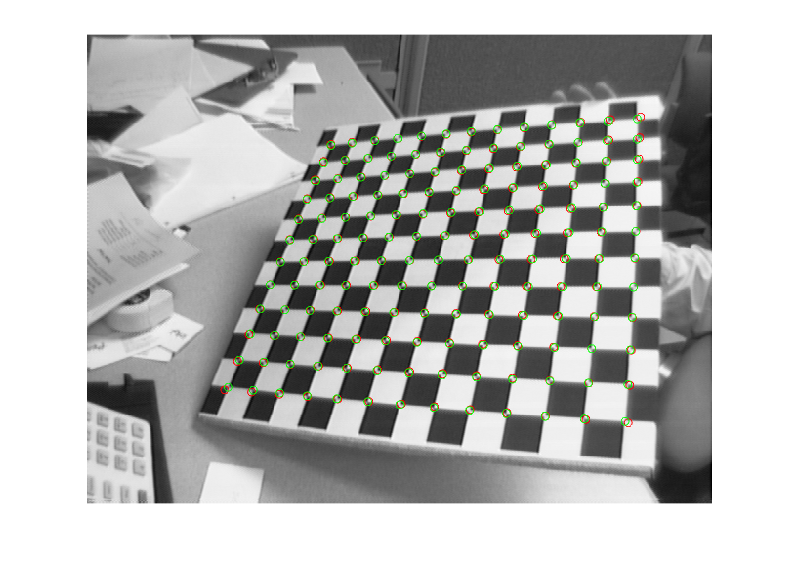

firstImage = imageData(1); 
XYmm    = firstImage.XYmm;
XYpixel = firstImage.XYpixel;
P       = firstImage.P;

figure
imshow(firstImage.I, 'InitialMagnification', 300)
hold on

tot_proj_error = 0;
for ii= 1:length(XYmm)
    % homogenous coordinates
    homog_real_world = [XYmm(ii,1); ... 
                        XYmm(ii,2); ...
                        0; ...
                        1];
    % projections
    proj_homographies  = P * homog_real_world; 
    projections = [proj_homographies(1)/proj_homographies(3); ...
                   proj_homographies(2)/proj_homographies(3);];

    % summing up the reprojection errors for every point in the checkerboard
    tot_proj_error = tot_proj_error + (projections(1)-XYpixel(ii,1))^2 + (projections(2)-XYpixel(ii,2))^2;

    plot(projections(1), projections(2), 'ro')
    plot(XYpixel(ii,1), XYpixel(ii,2), 'go')
end

disp(tot_proj_error)

  225.4673



## Superimposing a cylinder

For every image, to check qualitatively that the estimated P projects points in a correct way, the real world coordinates of a cylinder are taken: the cylinder consists in two circles at a different height with respect to the plane of the checkerboard, a red circle at height zero, and a green circle at height h = 50. Those coordinates are then transformed into their homogenous counterparts, projected into the image plane, and plotted using the inhomogenous coordinates.

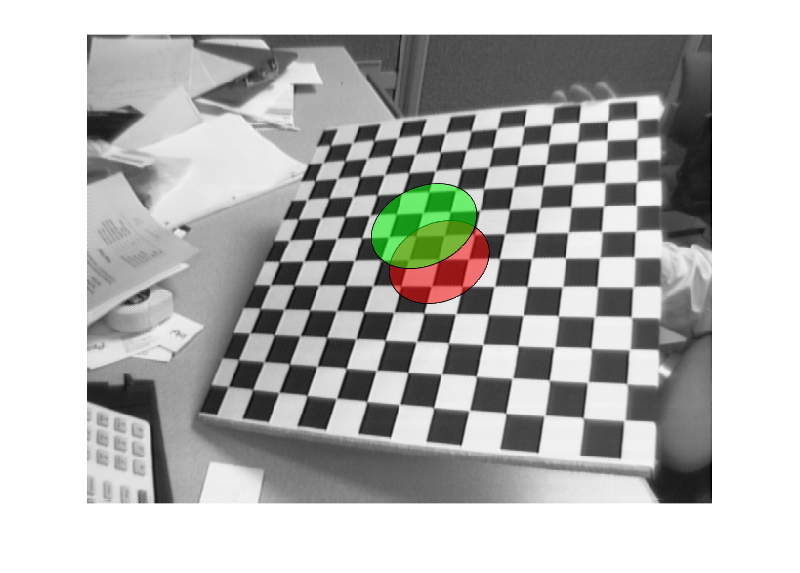

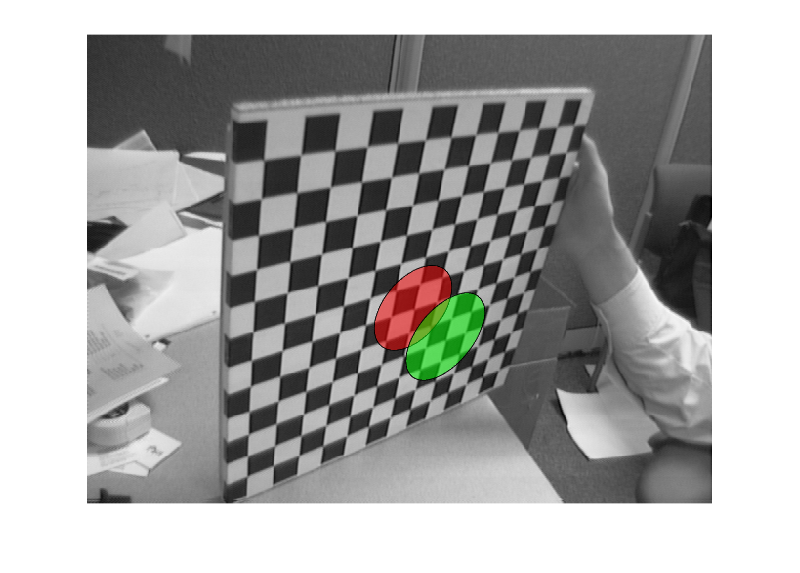

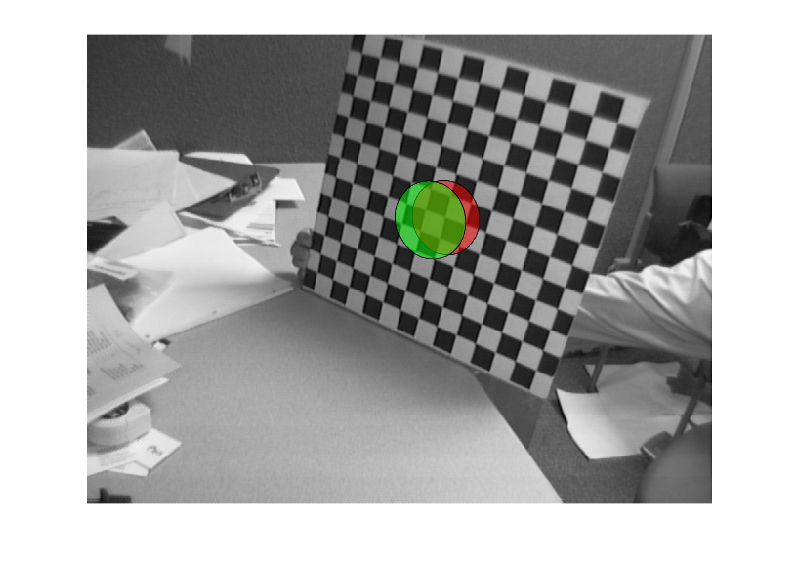

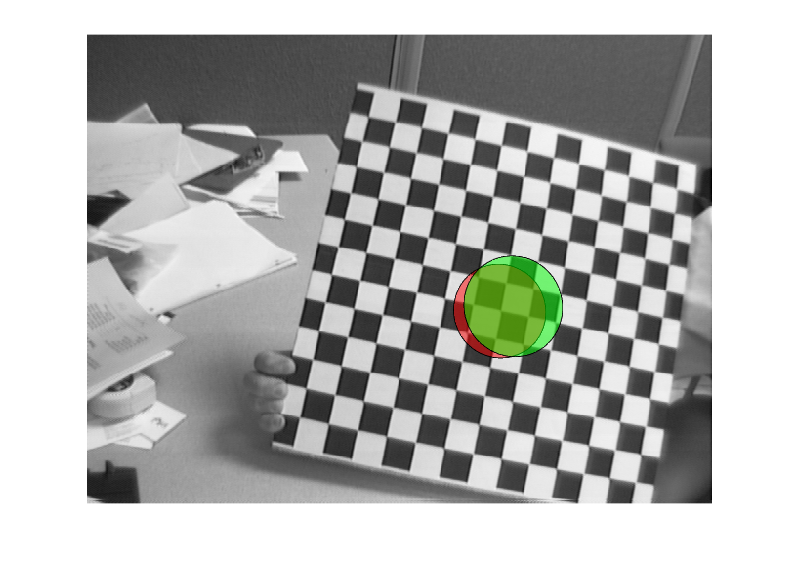

for ii=1:length(iimage)
    figure
    imshow(imageData(ii).I, 'InitialMagnification',200)
    hold on

    centerX = 180; 
    centerY = 180;                           % real world coordinates of the center of the circle
    radius  = 50;
    theta = 0:pi/50:2*pi;
    xunit = radius * cos(theta) + centerX;   % circumference of the 2D circle
    yunit = radius * sin(theta) + centerY;

    homogeneous = [xunit; yunit; ones(1,length(xunit))]; % circle in homogeneous coordinates
    proj_hom = imageData(ii).H*homogeneous; 
    proj = [ proj_hom(1,:)./proj_hom(3,:); ... 
             proj_hom(2,:)./proj_hom(3,:)];    
    fill(proj(1,:), proj(2,:), 'r','FaceAlpha',0.5);

    % drawing a second circle adding h: the cylinder height
    h = 50;
    homogeneous2 = [xunit; yunit; h*ones(1,length(xunit)); ones(1,length(xunit))]; 
    proj_hom2 = imageData(ii).P*homogeneous2; 
    proj2 = [ proj_hom2(1,:)./proj_hom2(3,:); ... 
             proj_hom2(2,:)./proj_hom2(3,:)];    
    fill(proj2(1,:), proj2(2,:), 'g','FaceAlpha',0.5);
    pause(1)
    hold off
end